# Data aggregation in food webs: effects on key positions

- Calculate centrality indices in the original food web

- Aggregate network & calculate centrality indices in the aggregated food webs (best link ratio & weight)

- Aggregate network & calculate centrality indices in the aggregated food webs (fixed link ratio & weight)

Left to do: 

- Code STO(W)

- Code predator modularity

## 1. Calculate centrality indices in the original food web

### 1.1 Import food web data

The following first lines import the adjacency matrix of the Gulf of Naples and the name of its nodes and thenplot the food web. 

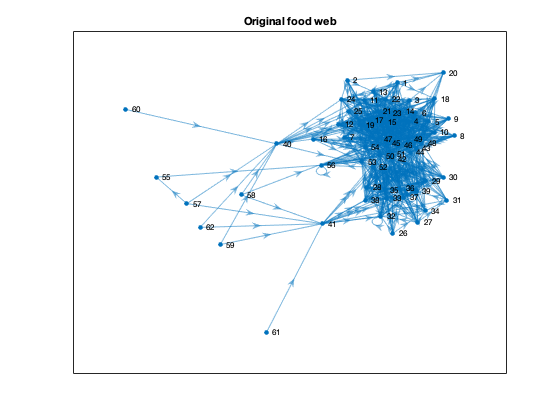

clc,clear; cd '/Users/ema/Github/Data_aggregation/Matlab_files'; warning('off','all');
A=readmatrix("../data/adjacency_matrix.txt"); n=length(A); network=digraph(A); network_U=graph(toundirected(A));
FID = fopen('../data/node_names.txt'); data = textscan(FID,'%s'); fclose(FID); node_names = string(data{:}); node_names = strrep(node_names,'_',' ');
plot(network),title("Original food web")

### 1.2 Calculate centrality

Then I calculate the centrality indices of the nodes of the original food web.

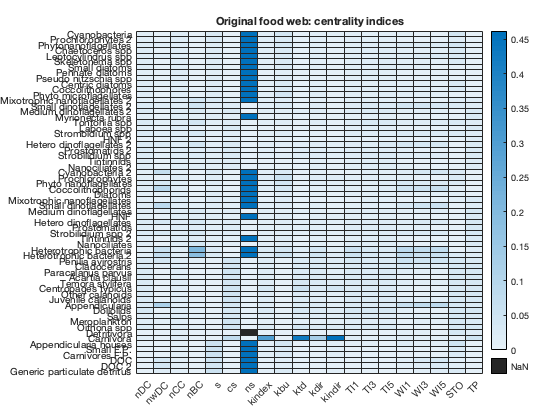

nDC = centrality(network_U,'degree')/(n-1);
nwDC = weightedDegree(A)/(n-1);
nCC = centrality(network_U,'closeness')*(n-1);
nBC = centrality(network,'betweenness')/((n-1)*(n-2)/2);
[s,cs,ns] = statusIndices(A);
[kindex,kbu,ktd,kdir,kindir] = keystoneIndices(A);
TI1 = topologicalImportance(A,1,"false");
TI3 = topologicalImportance(A,3,"false");
TI5 = topologicalImportance(A,5,"false");
WI1 = topologicalImportance(A,1,"true");
WI3 = topologicalImportance(A,3,"true");
WI5 = topologicalImportance(A,5,"true");
STO = topologicalOverlap(A,3,0.02,0.2,0.02);
TP = trophicPosition(A);
centralities_original=[nDC nwDC nCC nBC s cs ns kindex kbu ktd kdir kindir TI1 TI3 TI5 WI1 WI3 WI5 STO TP];

centralities=["nDC";"nwDC";"nCC";"nBC";"s";"cs";"ns";"kindex";"kbu";"ktd";"kdir";"kindir";"TI1";"TI3";"TI5";"WI1";"WI3";"WI5";"STO";"TP"]; c=length(centralities);
heatmap(centralities,node_names,(centralities_original./sum(centralities_original)),'Title','Original food web: centrality indices',"CellLabelFormat","%.2f");

where the values in the table are a in ratio format. Watch out: the sum of the net status (ns) of all the nodes is 0. So, for a node +inf means that its net status is positive, -inf means that its net status is negative and NaN means that its net status is 0.

## 2. Aggregate network & calculate centrality indices in the aggregated food webs (best link ratio & weight)

### 2.1. Clustering of nodes

At this point we can use our five clustering methods to find similar nodes:

- Hierarchical clustering with Jaccard index

- Hierarchical clustering with REGE index

- Modularity maximisation with density-based modularity

- Modularity maximisation with prey-based modularity

- Group model modules

#### Hierarchical clustering with Jaccard index

branches_jaccard = findBranches(A,"jaccard");
membership_jaccard=cluster(branches_jaccard,'cutoff',0.01);
%dendrogram(branches_jaccard,0,'Orientation','left')

#### Hierarchical clustering with REGE index

rege_similarity=readmatrix("../variables/REGE3");
branches_rege = findBranches(A,"rege",rege_similarity);
membership_rege=cluster(branches_rege,'cutoff',0.01);
%dendrogram(branches_rege,0,'Orientation','left')

#### Modularity maximisation with density-based modularity (previously calculated)

membership_density_modularity = readmatrix("../variables/density_based_results.txt");

#### Modularity maximisation with prey-based modularity (previously calculated)

membership_prey_modularity = readmatrix("../variables/prey_based_results.txt");

#### Group model modules (previously calculated)

membership_groups=readmatrix("../variables/group_model_results.txt");

Let's take a look at the membership of nodes to different clusters: 

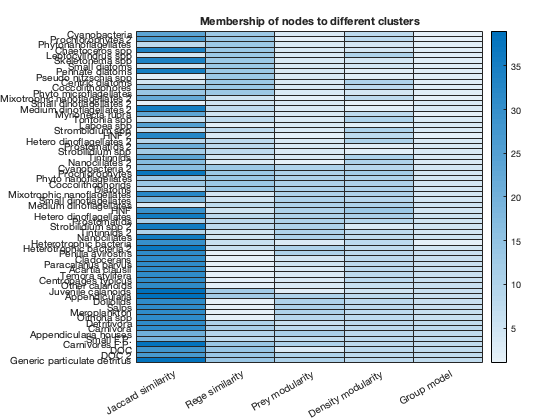

membership=[membership_jaccard membership_rege membership_prey_modularity membership_density_modularity membership_groups];
clear membership_jaccard membership_rege membership_prey_modularity membership_density_modularity membership_groups;

aggregations=["Jaccard_similarity";"Rege_similarity";"Prey_modularity";"Density_modularity";"Group_model"]; a=length(aggregations);
heatmap(membership,"XData",strrep(aggregations,'_',' '),"Ydata",node_names,"Title","Membership of nodes to different clusters")

where the numbers inside the table are the cluster to which a node belongs to. For example, Cyanobacteria when clustering according to Jaccard similarity belongs to the 24th module. Unfortunately Matlab (as far as I know) doesn't have any function to plot the membership of nodes to different modules/clusters directly on the network, which would have been a clearer representation. For this, I refer you to the R script.

### 2.2. Wiring of clusters

#### Choose link percentage and weight method

To wire the clusters we need to set two parameters:

- **Link percentage **- the link percentage of realised connections between clusters that define when there is a connection between them. Let's choose a set of percentages with the following code. Then we calculate the percenage of links that have been realised between clusters. 

cluster_size=cell(a,1); possible=cell(a,1); realised=cell(a,1); realised_ratio=cell(a,1);
for i=1:a 
    cluster_size{i}=clusterSize(membership(:,i));
    possible{i} = possibleConnections(cluster_size{i});
    realised{i} = realisedConnections(A,membership(:,i));
    realised_ratio{i}=realisedConnectionsRatio(possible{i},realised{i});
end

percentages=[0.001 0.05:0.05:1]; p=length(percentages);

- **Weight method **- the way we determine the strength of the connection between clusters. Let's choose the following ones. The minimum weight, the mean weight, the maximum weight and the sum of the weights. 

weight_method = ["min" "mean" "max" "sum"]; w=length(weight_method);

#### Find the best link percentage and weight method 

For each centrality index and aggregation method, connect the clusters by using the best weight method and the best percentage. These are defined as the ones that produce the highest Kendall's tau b when comparing the original food web with the newly aggregated food web. 

best_Kendall=inf(c,a)*-1; best_percentage=zeros(c,a); best_weight=strings(c,a); %best_weight(:)="binary";
A_clustered=cell(c,a); centrality_clusters=cell(c,a);  centrality_nodes=cell(c,a);
for i=1:a
    for j=1:c
        for k=1:p
            for l=1:w
                A_clustered_check = buildBinaryNetwork(realised_ratio{i}, percentages(k));
                if centralities(j)=="nwDC" || centralities(j)=="STO"
                    A_clustered_check = buildWeightedNetwork(A,A_clustered_check,membership(:,i),weight_method(l));
                end
                centrality_clusters_check = centralityClusters(A_clustered_check,centralities(j));
                centrality_nodes_check = centralityNodes(centrality_clusters_check, membership(:,i));
                if max(isnan(centrality_nodes_check))~=1 && max(isinf(centrality_nodes_check))~=1
                    Kendall_check = ktaub([centralities_original(:,j), centrality_nodes_check],0.05);
                end
                if Kendall_check > best_Kendall(j,i)
                    best_Kendall(j,i) = Kendall_check;
                    best_percentage(j,i) = percentages(k);
                    best_weight(j,i) = weight_method(l);
                    A_clustered{j,i} = A_clustered_check;
                    centrality_clusters{j,i}=centrality_clusters_check;
                    centrality_nodes{j,i}=centrality_nodes_check;
                end
            end
        end
    end
end


Taub Message: S = 0. P-value cannot = 100-percent. 
              P-value is adjusted using S = 1 and should be reported as p > 0.99515.

Taub Message: S = 0. P-value cannot = 100-percent. 
              P-value is adjusted using S = 1 and should be reported as p > 0.99515.

Taub Message: S = 0. P-value cannot = 100-percent. 
              P-value is adjusted using S = 1 and should be reported as p > 0.99515.

Taub Message: S = 0. P-value cannot = 100-percent. 
              P-value is adjusted using S = 1 and should be reported as p > 0.99515.

Taub Message: S = 0. P-value cannot = 100-percent. 
              P-value is adjusted using S = 1 and should be reported as p > 0.99515.

Taub Message: S = 0. P-value cannot = 100-percent. 
              P-value is adjusted using S = 1 and should be reported as p > 0.99515.

Taub Message: S = 0. P-value cannot = 100-percent. 
              P-value is adjusted using S = 1 and should be reported as p > 0.99515.

Taub Message: S = 0. P-value cann

#### Check best link percentage

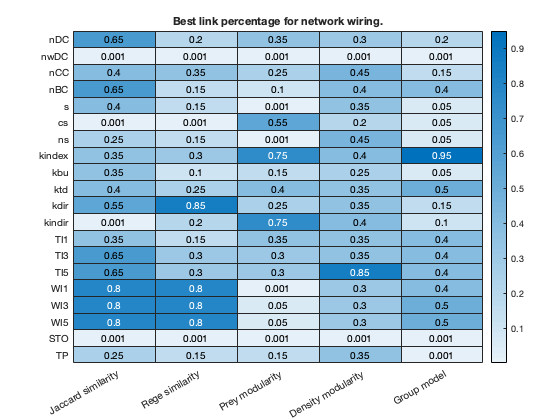

heatmap(strrep(aggregations,'_',' '),centralities,best_percentage,"Title","Best link percentage for network wiring.")

Now, we might want to ask whether there is a difference in the mean of the link percentage of the different aggregation methods. However, I think that my data might be biased by the way I selected the centrality indices. Let's take a look anyway.

sum(best_percentage)/n

ans =     0.1339    0.0968    0.0767    0.1081    0.0847


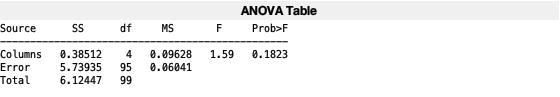

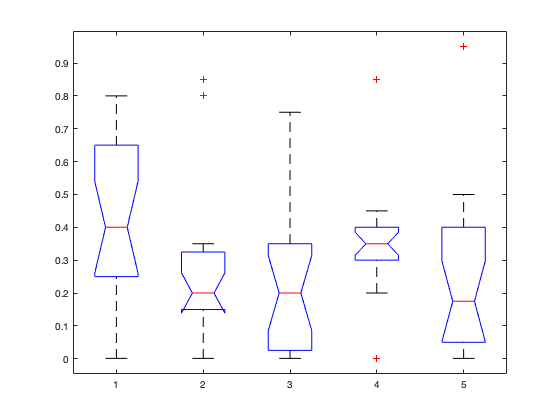

p = 0.1823

tbl = 4×6 cell array
    {'Source' }    {'SS'    }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Columns'}    {[0.3851]}    {[ 4]}    {[  0.0963]}    {[  1.5937]}    {[  0.1823]}
    {'Error'  }    {[5.7394]}    {[95]}    {[  0.0604]}    {0×0 double}    {0×0 double}
    {'Total'  }    {[6.1245]}    {[99]}    {0×0 double}    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: [5×1 char]
         n: [20 20 20 20 20]
    source: 'anova1'
     means: [0.4152 0.3002 0.2378 0.3351 0.2626]
        df: 95
         s: 0.2458


[p,tbl,stats] = anova1(best_percentage)

#### Check best weight method

best_weight

best_weight = 20×5 string array
    "min"    "min"     "min"    "min"    "min"
    "min"    "mean"    "min"    "min"    "sum"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"
    "min"    "min"     "min"    "min"    "min"


## 3. Compare aggregations

Start by creating a vector for each centrality.

for i=1:a
nDC = [nDC centrality_nodes{1,i}];
nwDC = [nwDC centrality_nodes{2,i}];
nCC = [nCC centrality_nodes{3,i}];
nBC = [nBC centrality_nodes{4,i}];
s = [s centrality_nodes{5,i}];
cs = [cs centrality_nodes{6,i}];
ns = [ns centrality_nodes{7,i}];
kindex = [kindex centrality_nodes{8,i}];
kbu = [kbu centrality_nodes{9,i}];
ktd = [ktd centrality_nodes{10,i}];
kdir = [kdir centrality_nodes{11,i}];
kindir = [kindir centrality_nodes{12,i}];
TI1 = [TI1 centrality_nodes{13,i}];
TI3 = [TI3 centrality_nodes{14,i}];
TI5 = [TI5 centrality_nodes{15,i}];
WI1 = [WI1 centrality_nodes{16,i}];
WI3 = [WI3 centrality_nodes{17,i}];
WI5 = [WI5 centrality_nodes{18,i}];
STO = [STO centrality_nodes{19,i}];
TP = [TP centrality_nodes{20,i}];
end

### 3.1. Compare different centrality indices for the same aggregation

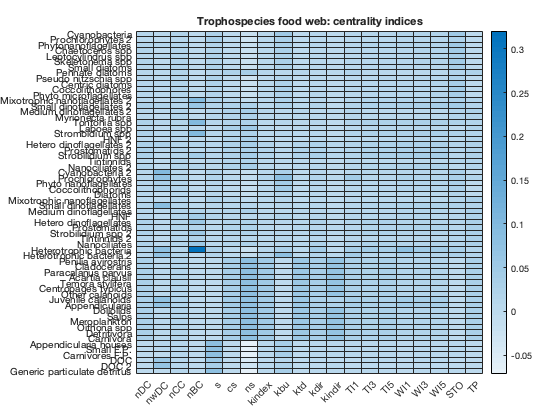

centralities_jaccard = [nDC(:,2) nwDC(:,2) nCC(:,2) nBC(:,2) s(:,2) cs(:,2) ns(:,2) kindex(:,2) kbu(:,2) ktd(:,2) kdir(:,2) kindir(:,2) TI1(:,2) TI3(:,2) TI5(:,2) WI1(:,2) WI3(:,2) WI5(:,2) STO(:,2) TP(:,2)];
heatmap(centralities,node_names,(centralities_jaccard./sum(centralities_jaccard)),'Title','Trophospecies food web: centrality indices',"CellLabelFormat","%.2f");

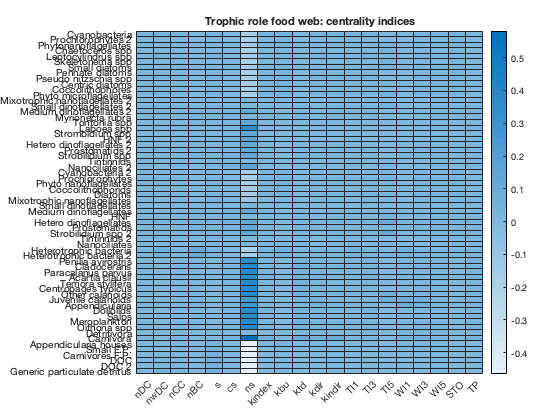

centralities_rege = [nDC(:,3) nwDC(:,3) nCC(:,3) nBC(:,3) s(:,3) cs(:,3) ns(:,3) kindex(:,3) kbu(:,3) ktd(:,3) kdir(:,3) kindir(:,3) TI1(:,3) TI3(:,3) TI5(:,5) WI1(:,3) WI3(:,3) WI5(:,5) STO(:,3) TP(:,3)];
heatmap(centralities,node_names,(centralities_rege./sum(centralities_rege)),'Title','Trophic role food web: centrality indices',"CellLabelFormat","%.2f");

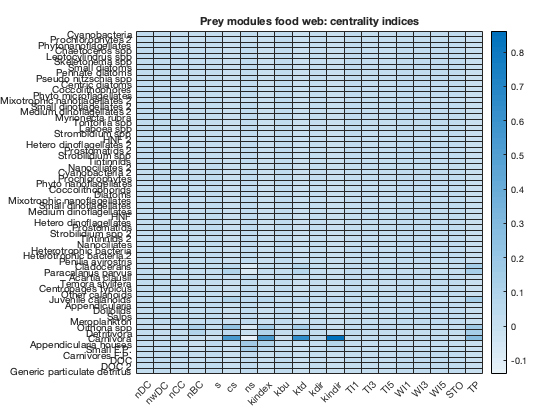

centralities_preymodules = [nDC(:,4) nwDC(:,4) nCC(:,4) nBC(:,4) s(:,4) cs(:,4) ns(:,4) kindex(:,4) kbu(:,4) ktd(:,4) kdir(:,4) kindir(:,4) TI1(:,4) TI3(:,4) TI5(:,4) WI1(:,4) WI3(:,4) WI5(:,4) STO(:,4) TP(:,4)];
heatmap(centralities,node_names,(centralities_preymodules./sum(centralities_preymodules)),'Title','Prey modules food web: centrality indices',"CellLabelFormat","%.2f");

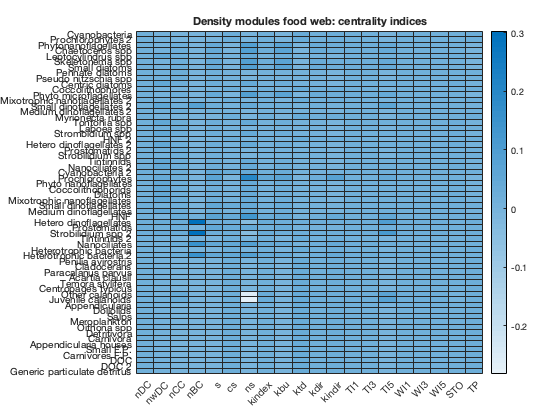

centralities_densitymodules = [nDC(:,5) nwDC(:,5) nCC(:,5) nBC(:,5) s(:,5) cs(:,5) ns(:,5) kindex(:,5) kbu(:,5) ktd(:,5) kdir(:,5) kindir(:,5) TI1(:,5) TI3(:,5) TI5(:,5) WI1(:,5) WI3(:,5) WI5(:,5) STO(:,5) TP(:,5)];
heatmap(centralities,node_names,(centralities_densitymodules./sum(centralities_densitymodules)),'Title','Density modules food web: centrality indices',"CellLabelFormat","%.2f");

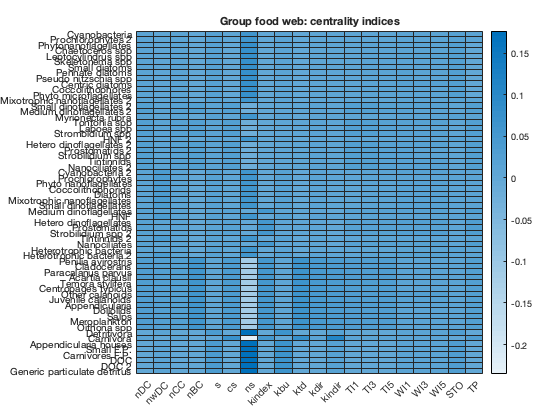

centralities_groups = [nDC(:,6) nwDC(:,6) nCC(:,6) nBC(:,6) s(:,6) cs(:,6) ns(:,6) kindex(:,6) kbu(:,6) ktd(:,6) kdir(:,6) kindir(:,6) TI1(:,6) TI3(:,6) TI5(:,6) WI1(:,5) WI3(:,5) WI5(:,5) STO(:,6) TP(:,6)];
heatmap(centralities,node_names,(centralities_groups./sum(centralities_groups)),'Title','Group food web: centrality indices',"CellLabelFormat","%.2f");

### 3.2 Compare different aggregations for the same centrality index

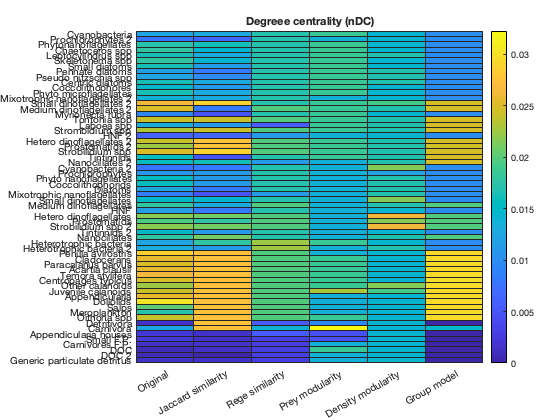

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,(nDC./sum(nDC)),"Title","Degreee centrality (nDC)","Colormap",parula,"CellLabelFormat","%.2f")

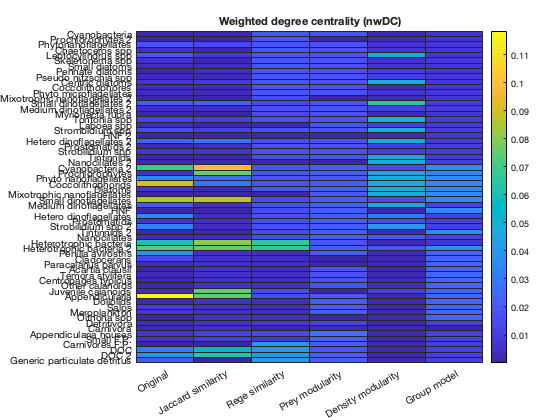

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,(nwDC./sum(nwDC)),"Title","Weighted degree centrality (nwDC)","Colormap",parula,"CellLabelFormat","%.2f")

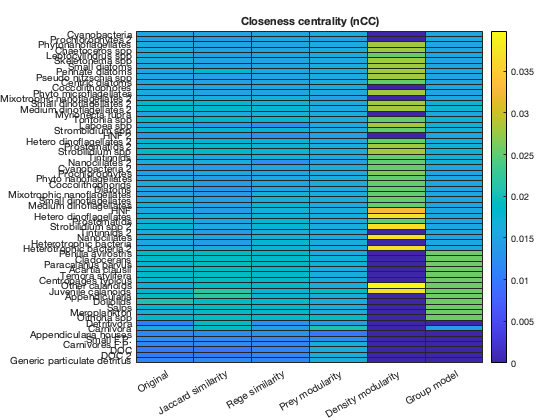

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,(nCC./sum(nCC)),"Title","Closeness centrality (nCC)","Colormap",parula,"CellLabelFormat","%.2f")

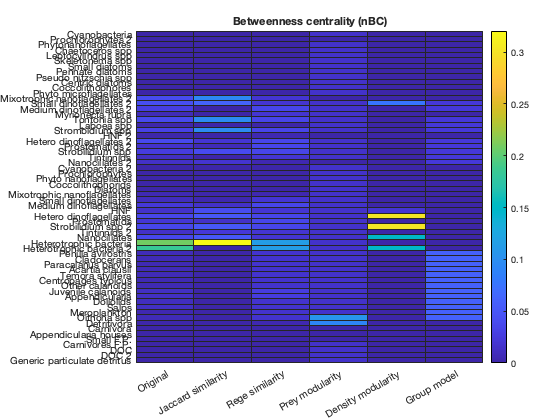

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,(nBC./sum(nBC)),"Title","Betweenness centrality (nBC)","Colormap",parula,"CellLabelFormat","%.2f")

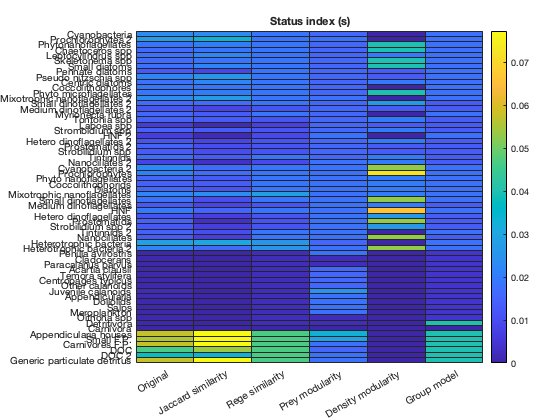

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,(s./sum(s)),"Title","Status index (s)","Colormap",parula,"CellLabelFormat","%.2f")

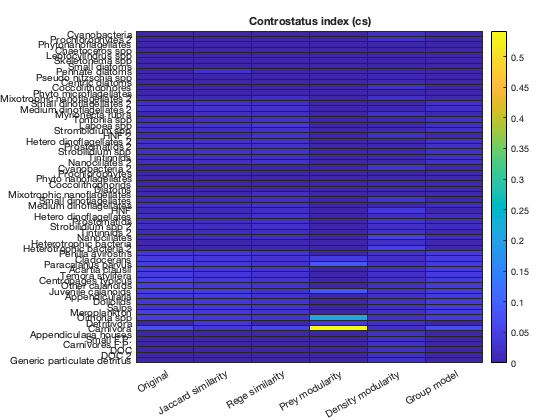

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,(cs./sum(cs)),"Title","Controstatus index (cs)","Colormap",parula,"CellLabelFormat","%.2f")

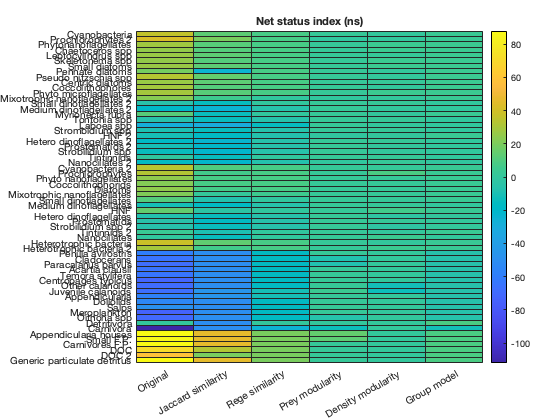

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,(ns),"Title","Net status index (ns)","Colormap",parula,"CellLabelFormat","%.2f")

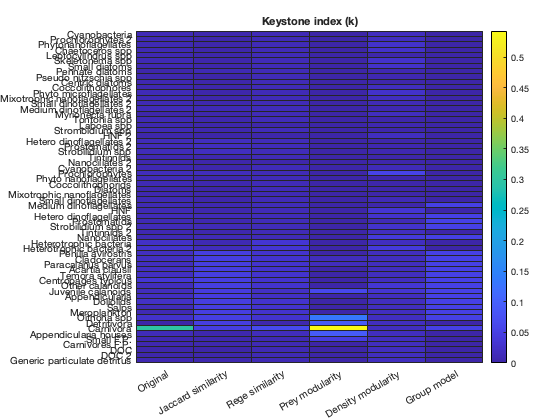

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,(kindex./sum(kindex)),"Title","Keystone index (k)","Colormap",parula,"CellLabelFormat","%.2f")

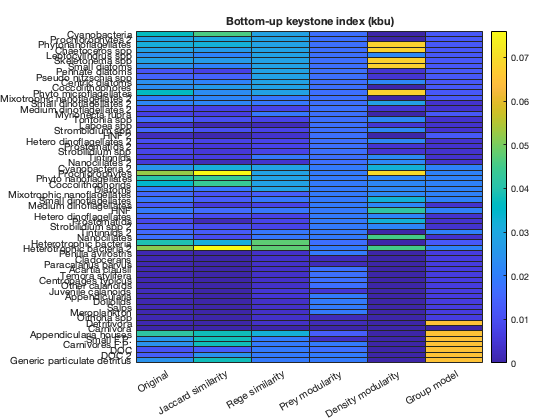

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,(kbu./sum(kbu)),"Title","Bottom-up keystone index (kbu)","Colormap",parula,"CellLabelFormat","%.2f")

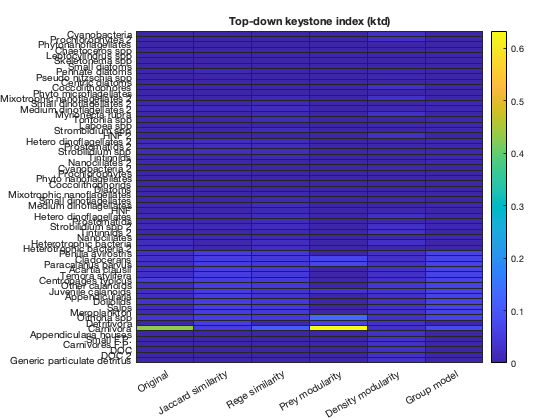

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,(ktd./sum(ktd)),"Title","Top-down keystone index (ktd)","Colormap",parula,"CellLabelFormat","%.2f")

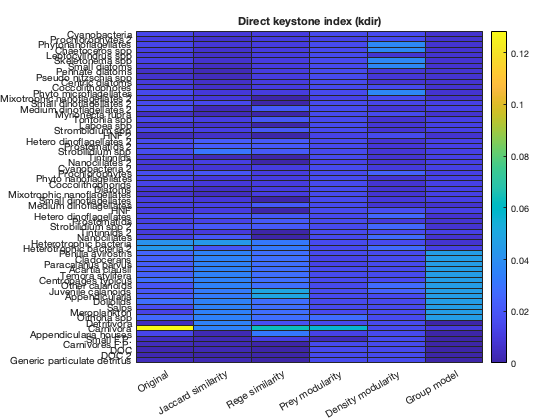

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,(kdir./sum(kdir)),"Title","Direct keystone index (kdir)","Colormap",parula,"CellLabelFormat","%.2f")

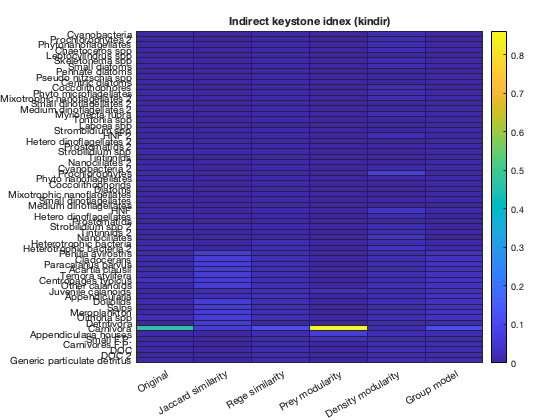

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,(kindir./sum(kindir)),"Title","Indirect keystone idnex (kindir)","Colormap",parula,"CellLabelFormat","%.2f")

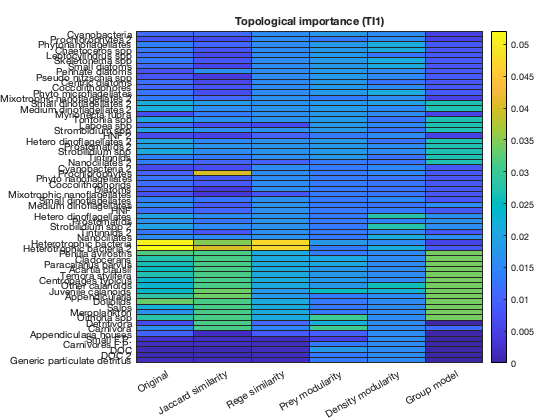

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,(TI1./sum(TI1)),"Title","Topological importance (TI1)","Colormap",parula,"CellLabelFormat","%.2f")

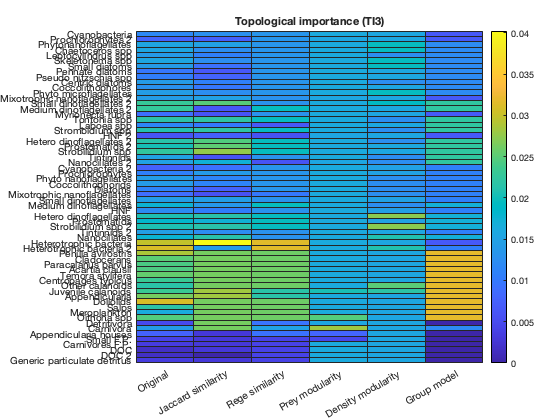

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,(TI3./sum(TI3)),"Title","Topological importance (TI3)","Colormap",parula,"CellLabelFormat","%.2f")

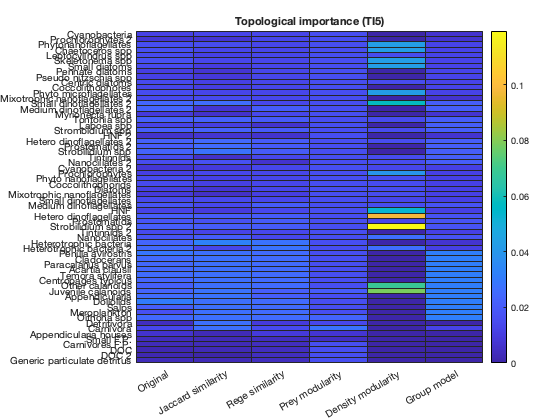

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,(TI5./sum(TI5)),"Title","Topological importance (TI5)","Colormap",parula,"CellLabelFormat","%.2f")

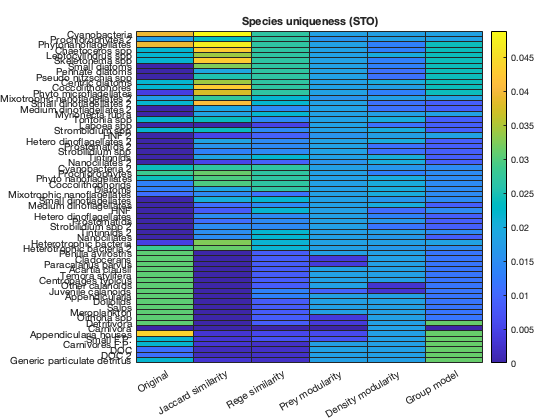

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,(STO./sum(STO)),"Title","Species uniqueness (STO)","Colormap",parula,"CellLabelFormat","%.2f")

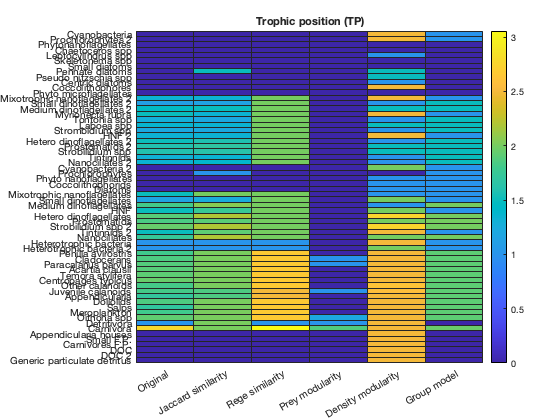

heatmap(["Original";strrep(aggregations,'_',' ')],node_names,TP,"Title","Trophic position (TP)","Colormap",parula,"CellLabelFormat","%.2f")

### 3.3 Correlation between the centrality indices in different aggregations

Here we are going to use the Kendall's tau b instead of Kendall's tau a because we are going to have a lot of ties (all the nodes inside a cluster have the same centrality). 

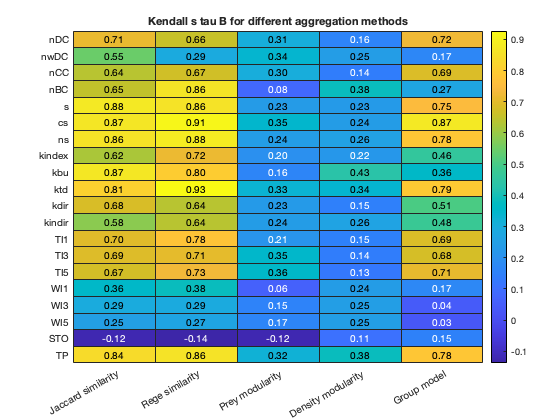

heatmap(strrep(aggregations,'_',' '),centralities,best_Kendall,"CellLabelFormat","%.2f",'Title','Kendall s tau B for different aggregation methods','Colormap',parula);

## 4. Aggregate network & calculate centrality indices in the aggregated food webs (fixed link ratio & weight)

A_clustered2=cell(a,1); centrality_clusters=cell(c,a);  centrality_nodes=cell(c,a); Kendall=zeros(c,a);
for i=1:a
    A_clustered2{i} = buildBinaryNetwork(realised_ratio{i}, 0.5);
    A_clustered2{i} = buildWeightedNetwork(A,A_clustered2{i},membership(:,i),"min");
    for j=1:c
        centrality_clusters{j,i} = centralityClusters(A_clustered2{i},centralities(j));
        centrality_nodes{j,i} = centralityNodes(centrality_clusters{j,i}, membership(:,i));
        if max(isnan(centrality_nodes{j,i}))~=1 && max(isinf(centrality_nodes{j,i}))~=1
            Kendall(j,i) = ktaub([centralities_original(:,j), centrality_nodes{j,i}],0.05);
        end
    end
end


Taub Message:  There was a significant trend = 0 found.


               Retested with ties set to equal number of positve and negative values.
               New p-value = 0.45314, but trend is not found to be significant.

Taub Message:  There was a significant trend = 0 found.
               Retested with ties set to equal number of positve and negative values.
               New p-value = 0.62642, but trend is not found to be significant.

Taub Message:  There was a significant trend = 0 found.
               Retested with ties set to equal number of positve and negative values.
               New p-value = 0.66652, but trend is not found to be significant.

Taub Message:  There was a significant trend = 0 found.
               Retested with ties set to equal number of positve and negative values.
               New p-value = 0.69803, but trend is not found to be significant.

Taub Message:  There was a significant trend = 0 found.
               Retested with ties set to equal number of positve and negative values.
               New p-v

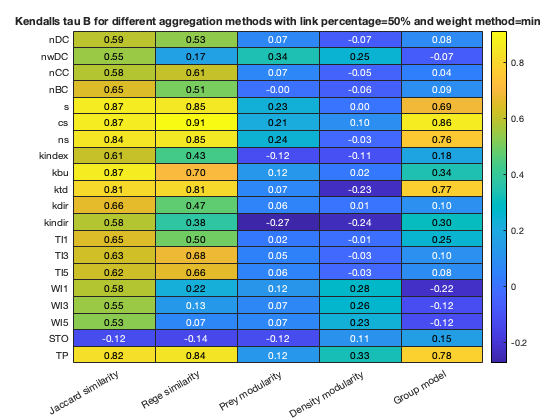

heatmap(strrep(aggregations,'_',' '),centralities,Kendall,"CellLabelFormat","%.2f",'Title','Kendalls tau B for different aggregation methods with link percentage=50% and weight method=min','Colormap',parula);

Let's now also plot the different food webs.

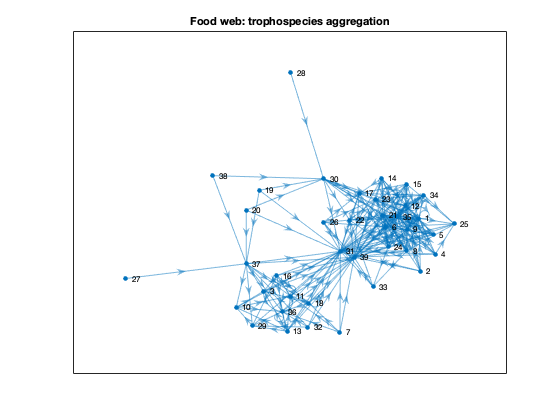

plot(digraph(A_clustered2{1})),title("Food web: trophospecies aggregation")

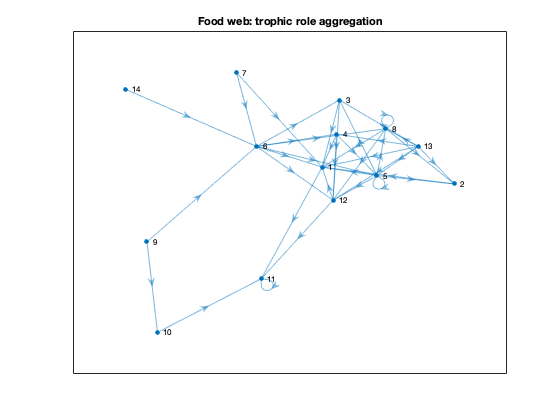

plot(digraph(A_clustered2{2})),title("Food web: trophic role aggregation")

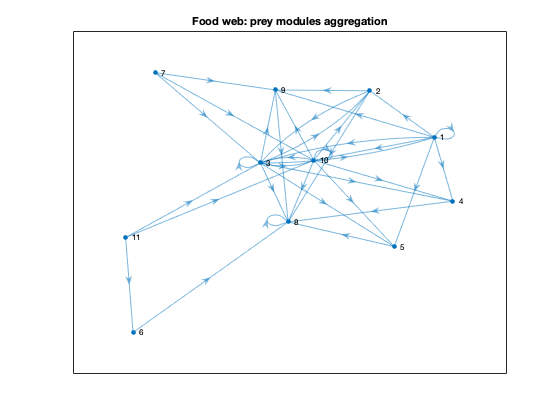

plot(digraph(A_clustered2{3})),title("Food web: prey modules aggregation")

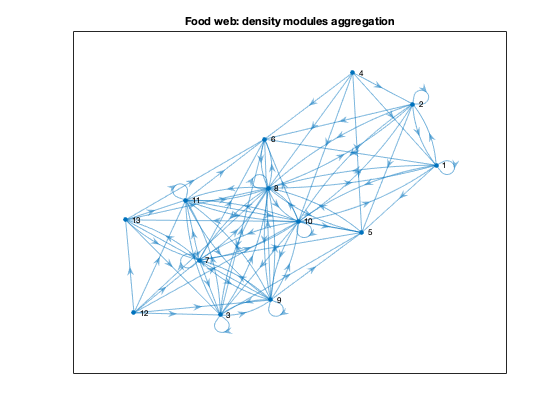

plot(digraph(A_clustered2{4})),title("Food web: density modules aggregation")

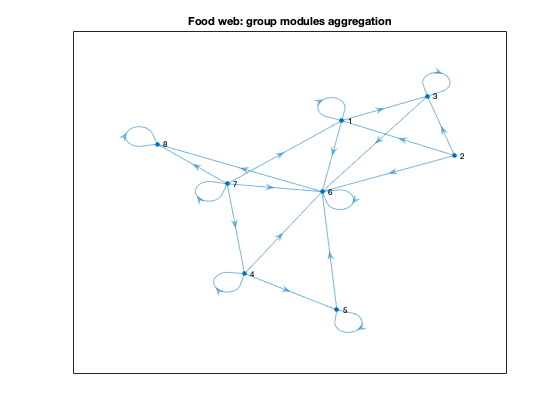

plot(digraph(A_clustered2{5})),title("Food web: group modules aggregation")

## Possible things I could do

- Calculate the Centrality Measure Correlations (CMCs). Now we want to know if the centrality indices are correlated to each other. This why we are going to use a Spearman's correlation, as in Oldham et al. (2019). Let's skip this part for now. 